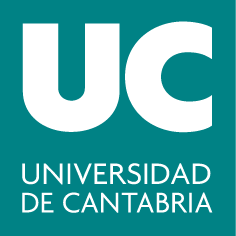

***Grados en Ingeniería de los Recursos Energéticos y de los Recursos Mineros***

**Cálculo**

# **3. Cálculo diferencial**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Funciones simbólicas

Para definir una función de variable simbólica:

clearvars % limpiamos la memoria
syms x
f(x) =  x^2+5; % definimos f(x)
class(f)

Hemos definido $f(x)$ como una función simbólica, `symfun`. Esto nos permite evaluar la función en cualquier punto directamente, sin necesidad de usar el comando `subs`.

f(3) % valor de la funcion f en x=3
f([1:10]) % vector de valores simbólicos

Se pueden definir varias variables simbólicas a la vez, así como el tipo exacto de variable con la que queremos trabajar:

De este modo resulta muy fácil definir, en modo simbólico, funciones de una variable real en MATLAB. Para representar gráficamente este tipo de funciones se utiliza el comando `fplot`.

**Ejemplo**: Representa la función $$f(x) = sen(x) + 3x + \frac{8}{x+1}$$ en el intervalo $$[-4, 4]$$.

syms x real  % defino 'x' como variable simbolica real
y(x) = sin(x) + 3*x + 8/(x+1) ; % defino f(x)
fplot(y, [-4, 4],'r')  % represento f(x) en [-4, 4]
grid on

### Límite

El comando` limit `permite calcular directamente el límite de una función, ya sea esta anónima o simbólica.

**Ejemplo:** Calculamos los siguientes límites:

a) $$\lim\limits_{x\to\infty} \frac{x^4 - x^3 + 5}{3x^4 + x^2 - 4x}$$

clearvars
syms x real                                  % defino x como variable simbolica real
f = @(x)  (x^4 - x^3 + 5) / (3*x^4 + x^2 - 4*x);  % funcion anonima
L = limit(f, x, inf)

Para pasar a formato decimal podemos recurrir al comando `double`:

Lnum = double(L)

b) $$\lim\limits_{x\to0} \frac{(1-\cos x)^2}{2sen^4x - sen^5x}$$

Podemos definir $f(x)$ como una función anónima

f = @(x)  (1-cos(x))^2 / (2*sin(x)^4 - sin(x)^5);
L = limit(f, x, 0)

#### Límites laterales

Los límites laterales:

- por la derecha: $$\lim\limits_{x \rightarrow a+} f(x) = \lim\limits_{h \rightarrow 0} f(a+h) $, $h>0$$

- por la izquierda: $$\lim\limits_{x \rightarrow a-} f(x) = \lim\limits_{h \rightarrow 0} f(a-h) $, $h>0$$

Recuerda que **el límite de una función en un punto existe si, y sólo si, existen los dos límites laterales en dicho punto y ambos coinciden:**


$$$$\lim\limits_{x \rightarrow a} f(x) = \ell  \Leftrightarrow\lim\limits_{x \rightarrow a+} f(x) =  \lim\limits_{x \rightarrow a-} f(x) = \ell$$$$


 **Ejemplo:** $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$

clearvars
syms x real  
f = sin(abs(x)) / x;

1. Calculamos límite por la derecha:

L_der = limit(f, x, 0, 'right') 

2. Calculamos límite por la izquierda:

L_izq = limit(f, x, 0, 'left') 

Ambos existen, pero no coinciden. Por lo tanto, el límite $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$ no existe:

L = limit(f, x, 0) 

#### Continuidad

A partir del cálculo de límites podemos estudiar la continuidad de una función. Para ello será conveniente conocer el comando `solve`, que permite resolver sistemas de ecuaciones. En el caso de una sola ecuación con una única incógnita, su sintaxis es la siguiente:

**Ejemplo: **Resolvemos la ecuación $x^2 - 5x-6 = 0$ 

syms x real
raices1 = solve(x^2 - 5*x - 6 == 0)   % raices ecuacion segundo grado --> x = {-1,6}
raices2 = solve(x^2 - 5*x - 6)        % equivalente a la orden anterior

El comando `solve` está diseñado para trabajar con expresiones simbólicas. Por tanto, en el caso de funciones anónimas, habría que convertirlas antes al tipo simbólico con ayuda del comando `sym`:

f = @(x)  4*x^2 - x;
% raices = solve(f)        % no permitido
raices = solve(sym(f))   % permitido --> x = {0, 1/4}

El resultado devuelto por` solve `también es una expresión simbólica:

R = double(raices)  % paso a decimal

**Ejemplo**: Estudia la continuidad de la función $$f(x) = \frac{x}{x^2-x}$$

1. Definimos la función: 

clearvars
syms x real
f(x) =  x / (x^2 - x);

2. Hallamos los puntos de discontinuidad: $f(x)$ no esta definida en los puntos en los que el denominador se anule:

puntos_discontinuidad = double(solve(x^2 - x)) 

3. Para estudiar si la discontinuidad es evitable o no, calculamos los límites:

- en $x = 0:$

L1 = limit(f, x, puntos_discontinuidad(1)) 

El límite existe, por lo tanto es una discontinuidad evitable.

- en $x = 1$:

L2 = limit(f, x, puntos_discontinuidad(2))  

El límite no existe, entonces en $x = 1$ la función tiene una discontinuidad inevitable.

4. Representamos gráficamente la función y marcamos el punto de discontinuidad evitable:

fplot(f,'b-')
grid on
hold on
plot(puntos_discontinuidad(1), L1,'ro')
hold off

En el punto de discontinuidad inevitable, la función presenta una asíntota vertical.

### Derivación

#### Definición

La derivada de una función $$f(x)$$ en punto $$a$ $viene dada por

			
$$	$$f'(a) = \lim\limits_{\Delta x \rightarrow 0} \frac{f(a+\Delta x)-f(a)}{\Delta x} $$$$


Así, podemos calcular la derivada por la definición:

#### Comando `diff`

Pero también podemos utilizar la función `diff`. Al igual que` limit, diff `acepta tanto funciones anónimas como simbólicas:

**Ejemplo**: Calculamos $ $f'(x)$ $siendo $$f(x) ={x^4 - x^3 + 5}$$ usando ambos comandos:

1. Definimos la función:

clearvars
syms x real
f(x) = (x^4 - x^3 + 5)   % funcion simbólica

2. Calculamos la derivada por la definición:

syms dx
df1(x) = limit ( (f(x+dx) - f(x))/dx, dx, 0)

3. Calculamos la derivada utilizando el comando `diff`: 

df2(x) = diff(f) 

Ambas opciones dan mismo resultado.

#### Derivadas de orden superior

Las **derivadas de orden superior** se refieren a la derivación repetida de una función. Para calcular la derivada de orden superior:

Por ejemplo, para la segunda derivada:

d2f(x) = diff(f, x, 2)  

**Ejercicio**: Calcula las derivadas de la función  $f(x) = sen(x)$ hasta el cuarto orden. Comprueba que $f^{(4)}(x) = f(x)$.

% escribe aquí el código:




Solución:

clearvars
syms x real
f(x) = sin(x);
df(x) = diff(f)
d2f(x) = diff(f, x, 2) % que es equivalente a d2f(x) = diff(df)
d3f(x) = diff(f,x,3)
d4f(x) = diff(f,x,4)

**Ejemplo: **Siendo $$f(x) = \frac{sen(x)^4}{x^2 + e^x}$$, calcula $$f'(\pi)$$ y$ $f''(-4)$$:

clearvars
syms x real

f(x) =  sin(x)^4 / (x^2 + exp(x));  % funcion simbólica
f_prima(x) = diff(f, x, 1);  % derivada de orden 1
f_prima2(x) = diff(f, x, 2);  % derivada de orden 2

f_prima_pi = double(f_prima(pi))  % f'(x=pi)
f_prima2_4 = double(f_prima2(-4))  % f''(x=-4)

## Aplicaciones

#### Recta tangente

Con lo que hemos visto ahora podríamos calcular (y dibujar) las rectas tangentes y normales a una curva dada.

- Recta tangente: $$$y-f(a) = f'(a)(x-a)$$$

- Recta normal (perpendicular a la recta tangente):$ $$y-f(a) =-\frac{1}{f'(a)}(x-a)$$$

**Ejemplo:** Calculamos las tangentes a $$f(x) = x^3 - 3x$$ que sean paralelas a la recta $ $y = 6x + 10$$. Representa en una misma figura$ $f(x)$$ (en rojo) y las tangentes halladas (con línea discontinua) en el dominio $$[-5, 5]$$. Pon un título y una leyenda adecuada. 

clearvars
syms x real
f(x) = x^3 - 3*x;  

Calculamos la primera derivada:

df(x) = diff(f, x)  % derivada de orden 1

Para encontrar una recta tangente a $f(x)$que sea paralela a la recta  $ $y = 6x + 10$$,  debemos hallar el punto en el cual la derivada  $f'(x)$  es igual a 6, ya que la pendiente de la tangente debe coincidir con la pendiente de la recta dada para que sean paralelas.

a = double(solve(df == 6))  

Son dos puntos. Hallamos las rectas tangentes en cada una:

rt1 = df(a(1))*(x-a(1)) + subs(f, a(1))  % eq. RT en x = a(1)
rt2 = df(a(2))*(x-a(2)) + subs(f, a(2))  % eq. RT en x = a(1)
fplot(f,[-5,5],'r');  hold on % dibujo f
fplot(rt1,'k--');  % dibujo recta tangente en x = a(1)
fplot(rt2,'b--');  % dibujo recta tangente en x = a(2)
grid on
legend('f(x)', 'RT1', 'RT2')
xlabel('eje x'), ylabel('eje y')
title('Rectas tangentes')
hold off

#### Polinomio de Taylor

El comando `taylor` de MATLAB permite calcular directamente el polinomio de Tayor (de cualquier grado) para una cierta función (en cualquier punto). Dicha función puede estar definida como anónima o como simbólica. El resultado que devuelve `taylor `es siempre una expresión simbólica.

Fíjate en que los argumentos de entrada `ExpansionPoint` y` Order` son opcionales. Si estos argumentos no se especifican, `taylor` calcula por defecto el polinomio de Taylor de grado 5 centrado en el punto $$x=0$$. Consulta la [documentación](https://es.mathworks.com/help/symbolic/sym.taylor.html) si quieres obtener más información.

**Ejemplo: **Utilizamos el comando `taylor` para calcular el polinomio de Taylor de grado 3 de la función $$f(x)=xsen(x+1)$$ en el punto $$x=0$$. A continuación, utiliza dicho polinomio para obtener un valor aproximado de $$0.15 \cdot sen(1.15)$$. ¿Qúe error porcentual se comete en la aproximación?

1. Definimos la función (podría ser anónima o simbólica):

syms x real  
f = @(x)  x*sin(x+1);  % funcion anonima
class(f)

2. Calculamos el polinomio de Taylor:

pt3= taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0
class(pt3) 

El resultado es una variable (expresión) simbólica. Sin embargo,  si añadimos el argumento  (`pt3(x) =` ...), el resultado será una función simbólica:

pt3(x) = taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0
class(pt3) 

3. Calculamos el valor exacto y valor aproximado:

ve = 0.15*sin(1.15)     % valor exacto
va = double(pt3(0.15))  % valor aproximado (necesitaremos que x=0.15)

4. Calculamos el error:

err = 100*abs((va-ve)/ve)  % error: 0.03%

### Ejercicios propuestos

1. Define las siguientes funciones (como funciones simbólicas) de una variable y halla el valor (numérico) en el punto$ $x=\pi$$.

- 
$$ $f(x) = \frac{x}{1+|x|}$$$
		

- 
$$ $f(x) = \frac{e^x + e^{-x}}{2}$  $$


- 
$$$f(x) = senh(x)$$$


- 
$$$\;g_1(x) = f_1(f_2(x))$  y $\;g_2(x) = f_2(f_1(x))$, con $f_1(x) = x^2+1$ y $\;f_2(x) = \frac{2}{x}$$$
	

% escribe aquí el código:





Solución:

soluciones(1)

2. Halla el punto $$P$$ donde se cortan las funciones$ $f(x) = \frac{2}{x}$$ y $$g(x) = \sqrt{x^2 - 3}$$. Representa en una misma figura $$f$$ (en rojo) y $$g$ $(en azul) en $$[0,5] \times [0,3]$$. Pon una leyenda que identifique cada curva y un título. Halla la ecuación de la tangente a cada curva en $$P$$, dibuja ambas rectas (en el mismo color que la curva correspondiente pero en línea discontinua) y comprueba que son perpendiculares. 

% escribe aquí el código:





Solución:

soluciones(2)

3. Considera la función $$f(x)=x^4-5x^3+5x^2+x+2$$

- Calcula el polinomio de Taylor de grado 1 de $$f$$ en $$x=2$$. Comprueba que se trata de la recta tangente a $$f$$ en dicho punto.

- Calcula los polinomios de Taylor de grado 2,3,4,5,10. ¿Qué ocurre a partir de grado 4?

% escribe aquí el código:




Solución:

soluciones(3)

### Resumen

**Definir función simbólica**:

**Gráficos**

- `fplot(f(x),[x1 x2])`: graficar$ f(x) $ en el intervalo [x1, x2], $ f(x) $ puede ser una función simbólica o anónima.

- `fimplicit(ecuacion, [x1 x2 y1 y2]): `graficar $f(x,y) = 0$ (función implícita)

- `xlabel('Eje x'), ylabel('Eje y'): `etiquetar los ejes.

- `title('Título'): `añadir título

- `grid on: `activa la rejilla en el fondo

- `legend('Descripción 1', 'Descripción 2'): `agregar leyenda

- `axis equal: `Establecer la misma longitud para las unidades de datos a lo largo de cada eje.

**Límite**

- [`limit`](https://es.mathworks.com/help/symbolic/sym.limit.html)**:** Se utiliza para calcular el límite (y los límites laterales) de una función, ya sea anónima o simbólica. 

- [`solve`](https://es.mathworks.com/help/symbolic/sym.solve.html)**:** Se emplea para resolver ecuaciones simbólicas (por ejemplo, para encontrar puntos de discontinuidad en la función).

**Derivación**

- [`diff`](https://es.mathworks.com/help/symbolic/diff.html)**:** Calcula la derivada de una función de manera simbólica. También permite calcular derivadas de orden superior.

**Polinomio de Taylor**

- [`taylor`](https://es.mathworks.com/help/symbolic/sym.taylor.html)**:** Calcula el polinomio de Taylor de una función, permitiendo especificar el punto de expansión y el grado del polinomio. Los argumentos adicionales como el punto de expansión y el grado son opcionales; si no se especifican, se calcula un polinomio de Taylor de grado 5 centrado en 0.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n ");
        syms x
        f(x) = x/(1+abs(x))
        f1 = double(f(pi))
        f(x) = (exp(x) + exp(-x))/2
        f2 = double(f(pi))
        f(x) = sinh(x)
        f3 = double(f(pi))
        f_1(x) = x^2+1;
        f_2(x) = 2/x;
        g_1(x) = f_1(  f_2 (x) )

        g1 = double(g_1(pi))
        g_2(x) = f_2(  f_1 (x) )
        g2 = double(g_2(pi))

    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        syms x real
        f(x) = 2/x;
        g(x) = sqrt(x^2-3);
        fplot(f,[0 5],'r')
        hold on
        fplot(g,[0,5],'b')

        df(x) = diff(f);
        dg(x) = diff(g);
        P = solve(f-g);
        rt1(x) = df(P)*(x-P) + f(P);
        rt2(x) = dg(P)*(x-P) + g(P);

        fplot(rt1,[0 5],'r--')
        fplot(rt2,[0,5],'b--')

        axis equal
        ylim ([0 3])
        grid on
        legend('f(x)','g(x)','RT(f)','RT(g)')
        hold off
    case 3
        fprintf("Ejercicio 3:\n");
        syms x real
        f(x) = x^4 -5*x^3 + 5*x^2 + x + 2;
        a = 2;
        %Polinomio de Taylor:

        pt1(x) = taylor(f,x,a,'Order',2);
        % Recta tangente:
        df = diff(f);

        rt(x) = df(a)*(x-a) + f(a);
        fprintf("Polinomio de Taylor: P1(x) = %s,\nRecta Tangente:          y = %s\n",char(pt1),char(rt))
        for k = [2,3,4,5,10]
            fprintf("Orden %d: ",k)
            pt(x) = taylor(f,x,a,'Order',k+1)
        end
        fprintf("A partir de grado 4, todos los polinomios de Taylor son idénticos. \nEsto se debe a que la función original es un polinomio de grado 4, \npor lo que su polinomio de Taylor de grado 4 ya es la expresión exacta. \nLos términos adicionales en polinomios de mayor grado serán cero, \nya que las derivadas de quinto orden en adelante son cero.\n")

    case 4
        fprintf("Ejercicio 4:\n");
        clearvars
        close all
        syms x real
        f1(x) = cos(x^2)
        fplot(f1,'b-')
        fprintf("Dominio: R; Imagen: [-1, 1]; Simetría: par\n------------------------------\n");
        f2(x) = cos(x)^2
        figure,
        fplot(f2,'r-')
        fprintf("Dominio: R; Imagen: [0, 1]; Simetría: par\n------------------------------\n");
        f3(x) = cos(x^2)^2
        figure,
        fplot(f3,'g-')
        fprintf("Dominio: R; Imagen: [0, 1]; Simetría: par\n------------------------------\n");
        f4(x) = sqrt(x^3)
        figure,
        fplot(f4,'k-')
        fprintf("Dominio: [0, Inf); Imagen: [0, Inf]; Simetría: no tiene\n");

end
end